# Derive and apply the inverse Kinematics of a DOUBLE compound **Pendulum**

In this task we're going to derive and then implement the inverse kinematics for a DOUBLE compound pendulum.  The system that we're going to explore is shown below:

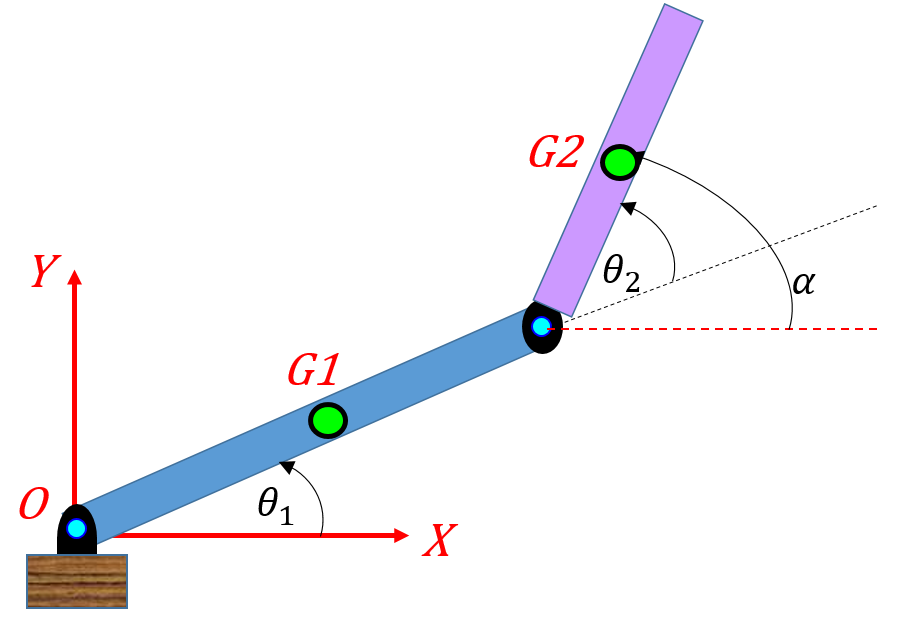     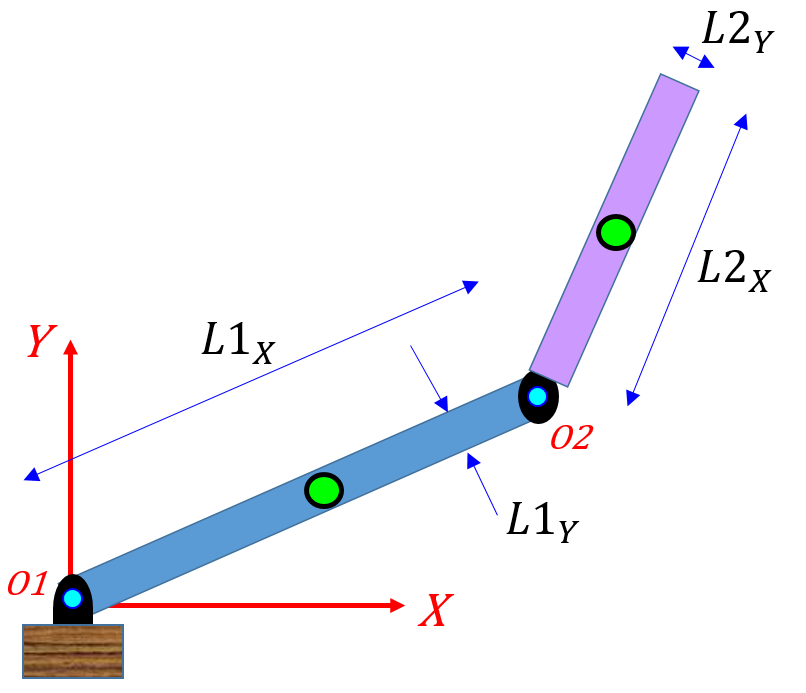   

## Defining some geometry parameters:

my_L1    = 1;
my_L2    = 0.5; 

syms theta_1 theta_2 L_1 L_2 XE YE

## Define the X,Y position of the End effector:

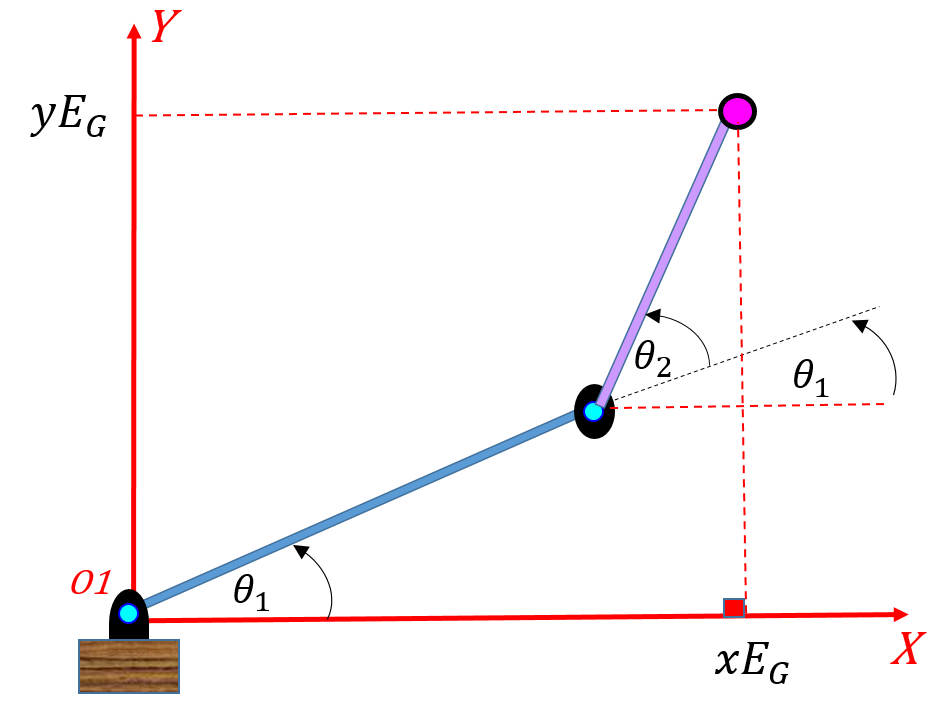

Here's are the **X** and **Y** co-ordinates of the end effector:

the_XE_RHS = L_1*cos(theta_1) + L_2*cos(theta_1 + theta_2)

$$the\_XE\_RHS = L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)$$

the_YE_RHS = L_1*sin(theta_1) + L_2*sin(theta_1 + theta_2)

$$the\_YE\_RHS = L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)$$

And I'm going to convert these symbolic expresions into MATLAB functions (say MLF):

XE_MLF     = matlabFunction(the_XE_RHS, 'Vars', [L_1, L_2, theta_1, theta_2]);
YE_MLF     = matlabFunction(the_YE_RHS, 'Vars', [L_1, L_2, theta_1, theta_2]);

## Visualise the FORWARD Kinematics:  $\theta \longrightarrow f(\theta) \longrightarrow (X_E,Y_E)$

For specific values of theta .. what is X,Y ?  Generate some X and Y data for a selection of angles

t1_degs_row          = linspace(   0, 90, 1000);
t2_degs_row          = linspace(-180,180, 1000);
[tt1_degs, tt2_degs] = meshgrid(t1_degs_row, t2_degs_row);

For any calcs we should use radians/sec:

tt1_rads  = tt1_degs * pi/180;
tt2_rads  = tt2_degs * pi/180;

So let's try and visualize this:

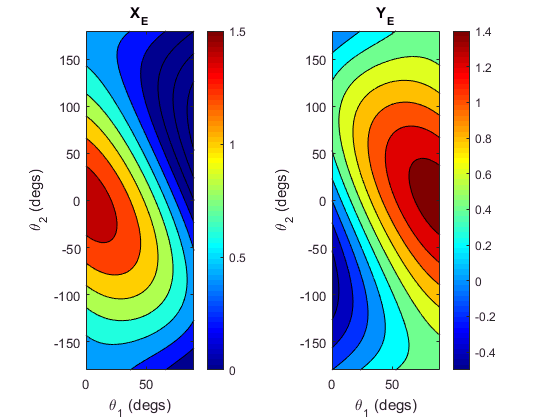

% here we're using our MATLAB functions(MLF) that we created earlier
my_X_mat   = XE_MLF(my_L1, my_L2, tt1_rads, tt2_rads); 
my_Y_mat   = YE_MLF(my_L1, my_L2, tt1_rads, tt2_rads); 

bh_2dof_plot_XY_given_theta( tt1_degs, tt2_degs, ...
                             my_X_mat, my_Y_mat, ...
                            (my_L1 + my_L2) )

## Compute the INVERSE  Kinematics:  $(X_E,Y_E) \longrightarrow g(X_E, Y_E) \longrightarrow (\theta_1, \theta_2)$

Start with the FORWARD kinematics expressions

XE_EQ  = XE == the_XE_RHS;
YE_EQ  = YE == the_YE_RHS;

Now solve for $\theta_1$ and $\theta_2$:

S      = solve([XE_EQ, YE_EQ], [theta_1, theta_2])

S =     theta_1: [2x1 sym]
    theta_2: [2x1 sym]


We actually get multiple solutions.   Here's the pair of solutions for $\theta_1$

simplify( S.theta_1 )

$$ans = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{2\,L_{1}\,\mathrm{YE}+\sigma_{1}}{{L_{1}}^{2}+2\,L_{1}\,\mathrm{XE}-{L_{2}}^{2}+{\mathrm{XE}}^{2}+{\mathrm{YE}}^{2}}\right)\\ 2\,\mathrm{atan}\left(\frac{2\,L_{1}\,\mathrm{YE}-\sigma_{1}}{{L_{1}}^{2}+2\,L_{1}\,\mathrm{XE}-{L_{2}}^{2}+{\mathrm{XE}}^{2}+{\mathrm{YE}}^{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-{L_{1}}^{4}+2\,{L_{1}}^{2}\,{L_{2}}^{2}+2\,{L_{1}}^{2}\,{\mathrm{XE}}^{2}+2\,{L_{1}}^{2}\,{\mathrm{YE}}^{2}-{L_{2}}^{4}+2\,{L_{2}}^{2}\,{\mathrm{XE}}^{2}+2\,{L_{2}}^{2}\,{\mathrm{YE}}^{2}-{\mathrm{XE}}^{4}-2\,{\mathrm{XE}}^{2}\,{\mathrm{YE}}^{2}-{\mathrm{YE}}^{4}} \end{array}$$

And here's the pair of solutions for $\theta_2$ :

S.theta_2

$$ans = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\mathrm{atan}\left(\frac{\sqrt{\left(-{L_{1}}^{2}+2\,L_{1}\,L_{2}-{L_{2}}^{2}+{\mathrm{XE}}^{2}+{\mathrm{YE}}^{2}\right)\,\left({L_{1}}^{2}+2\,L_{1}\,L_{2}+{L_{2}}^{2}-{\mathrm{XE}}^{2}-{\mathrm{YE}}^{2}\right)}}{-{L_{1}}^{2}+2\,L_{1}\,L_{2}-{L_{2}}^{2}+{\mathrm{XE}}^{2}+{\mathrm{YE}}^{2}}\right) \end{array}$$

And I'm going to convert these symbolic expresions into MATLAB functions (say MLF):

TH1_MLF{1} = matlabFunction(S.theta_1(1), 'Vars', [L_1, L_2, XE, YE]);
TH1_MLF{2} = matlabFunction(S.theta_1(2), 'Vars', [L_1, L_2, XE, YE]);

TH2_MLF{1} = matlabFunction(S.theta_2(1), 'Vars', [L_1, L_2, XE, YE]);
TH2_MLF{2} = matlabFunction(S.theta_2(2), 'Vars', [L_1, L_2, XE, YE]);

## Visualise the INVERSE Kinematics - SOLUTION #1

## 
$$(X_E,Y_E) \longrightarrow g(X_E, Y_E) \longrightarrow (\theta_1, \theta_2)$$


Generate a mesh of X,Y co-ordinates that we'd like to compute $\theta_1$ and $\theta_2$ for.  When we create this X,Y mesh some of the  X,Y co-ordinates will be beyond the reachable workspace of the end effector (eg: X,Y = 1.5,1.5). So? - So when we use our inverse kinematics expressions, some of our thetas will be imaginary ... and we'll need to correct this.

% Here's our mesh of X,Y co-ordinates
[xmat, ymat] = meshgrid([0:0.01:1.5], [0:0.01:1.5]);

% compute inverse kinematics
tmp_th1_mat  = TH1_MLF{1}(my_L1, my_L2, xmat, ymat);
tmp_th2_mat  = TH2_MLF{1}(my_L1, my_L2, xmat, ymat);

% convert to degrees
tmp_th1_mat = (180/pi)*tmp_th1_mat ;
tmp_th2_mat = (180/pi)*tmp_th2_mat ;

Here's where we correct for the NaN's :

% replace imaginary numbers
th1_mat = NaN*ones(size(tmp_th1_mat));
th2_mat = NaN*ones(size(tmp_th2_mat));

tf_mat= imag(tmp_th1_mat)==0;  th1_mat(tf_mat)= real(tmp_th1_mat(tf_mat));
tf_mat= imag(tmp_th2_mat)==0;  th2_mat(tf_mat)= real(tmp_th2_mat(tf_mat));

Now let's visualise this:

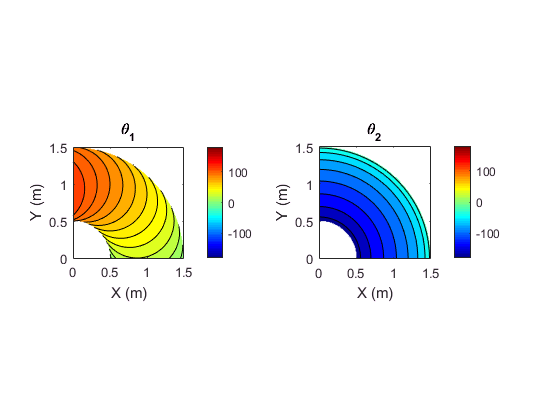

% plot it
bh_2dof_plot_theta_given_XY( xmat,    ...
                             ymat,    ...
                             th1_mat, ...
                             th2_mat)

## Visualise the INVERSE Kinematics - SOLUTION #2

## 
$$(X_E,Y_E) \longrightarrow g(X_E, Y_E) \longrightarrow (\theta_1, \theta_2)$$


Generate a mesh of X,Y co-ordinates that we'd like to compute $\theta_1$ and $\theta_2$ for.  When we create this X,Y mesh some of the  X,Y co-ordinates will be beyond the reachable workspace of the end effector (eg: X,Y = 1.5,1.5). So? - So when we use our inverse kinematics expressions, some of our thetas will be imaginary ... and we'll need to correct this.

% Here's our mesh of X,Y co-ordinates
[xmat, ymat] = meshgrid([0:0.01:1.5], [0:0.01:1.5]);

% compute inverse kinematics
tmp_th1_mat  = TH1_MLF{2}(my_L1, my_L2, xmat, ymat);
tmp_th2_mat  = TH2_MLF{2}(my_L1, my_L2, xmat, ymat);

% convert to degrees
tmp_th1_mat = (180/pi)*tmp_th1_mat ;
tmp_th2_mat = (180/pi)*tmp_th2_mat ;

Here's where we correct for the NaN's :

% replace imaginary numbers
th1_mat = NaN*ones(size(tmp_th1_mat));
th2_mat = NaN*ones(size(tmp_th2_mat));

tf_mat= imag(tmp_th1_mat)==0;  th1_mat(tf_mat)= real(tmp_th1_mat(tf_mat));
tf_mat= imag(tmp_th2_mat)==0;  th2_mat(tf_mat)= real(tmp_th2_mat(tf_mat));

Now let's visualise this:

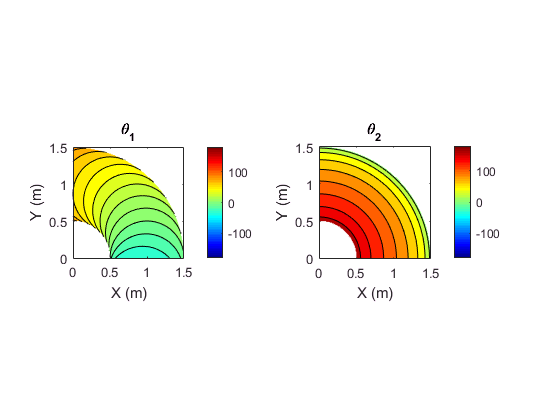

% plot it
bh_2dof_plot_theta_given_XY( xmat, ...
                             ymat, ...
                             th1_mat, ...
                             th2_mat)

## Compute our system Jacobian:

The system Jacobian is defined as:


$$J = \frac{d(X,Y)}{d(\theta_1, \theta_2)} = 
\pmatrix{
\frac{dX}{d\theta_1} & \frac{dX}{d\theta_2} \cr
\frac{dY}{d\theta_1} & \frac{dY}{d\theta_2} \cr

}$$


the_J = jacobian( [the_XE_RHS, the_YE_RHS],[theta_1, theta_2]  )

$$the\_J = \left(\begin{array}{cc} -L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-L_{1}\,\sin\left(\theta_{1}\right) & -L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right) & L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}\right)$$

We can use the Jacobian in the following way:


$$\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt}
} = 

\pmatrix{
\frac{dX}{d\theta_1} & \frac{dX}{d\theta_2} \cr
\frac{dY}{d\theta_1} & \frac{dY}{d\theta_2} \cr
} . 
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt}
}$$



$$\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt}
} = 

J . 
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt}
}$$


So we can then write:


$$
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt}
} = 
J^{+} \enspace . \enspace  
\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt}
} 
\enspace \enspace \textstyle{where} \enspace J^+ \enspace \text{is the Moore-Penrose pseudoinverse of J}$$
 

We can convert the symbolic expression of the Jacobian into a MATLAB function block

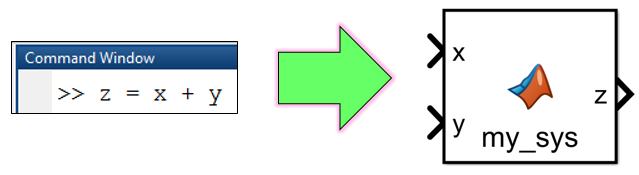

tf_i_should_create_SL_block = false;
if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_ikin_2dof';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
                  
    % convert J into a MATLAB function block(MLF)
    matlabFunctionBlock( [MODEL_NAME,'/THE_J'], ...
                         the_J, ...
                         'Optimize', false  );
    % why not convert the FORWARD kinematic expressions 
    % into MLF blocks too !                     
    matlabFunctionBlock( [MODEL_NAME,'/THE_XEYE'], ...
                         the_XE_RHS, the_YE_RHS, ...
                         'Optimize', false, ...
                         'Outputs', {'XE', 'YE'}   );                           
end

## Apply these concepts:

bh_parameters_for_DOUBLE_compound_pendulum

theta1_0     =  0;                    % rad
theta1_dot_0 =  0;                    % rad/sec 
theta2_0     =  0;                    % rad
theta2_dot_0 =  0;                    % rad/sec

In the Simulink model `<bh_test_J_DBL_pend.slx>` we've applied the expressions that we derived earlier for the Jacobian and the FORWARD kinematics.  They look like this:

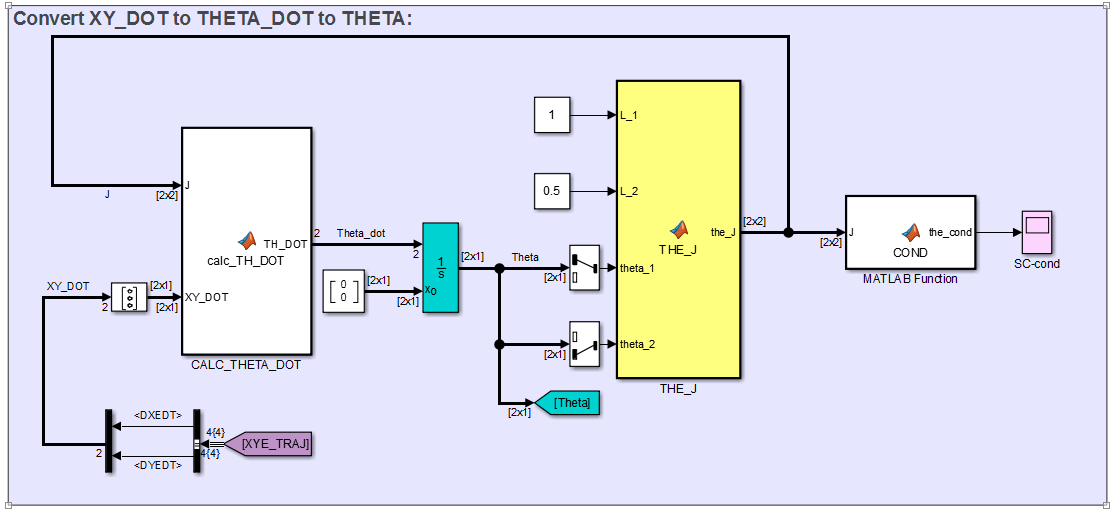

Note that the blocks above, are implmenting our previouslly derived equation of:


$$
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt}
} = 
J^{+} \enspace . \enspace  
\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt}
} $$


In this model, here's what the $\dot{X}_E$ and $\dot{Y}_E$signals look like - these end effector velocities are defined in an EXCEL file called <`bh_hello_complete.xlsx`>, which we read within the Simulink model.

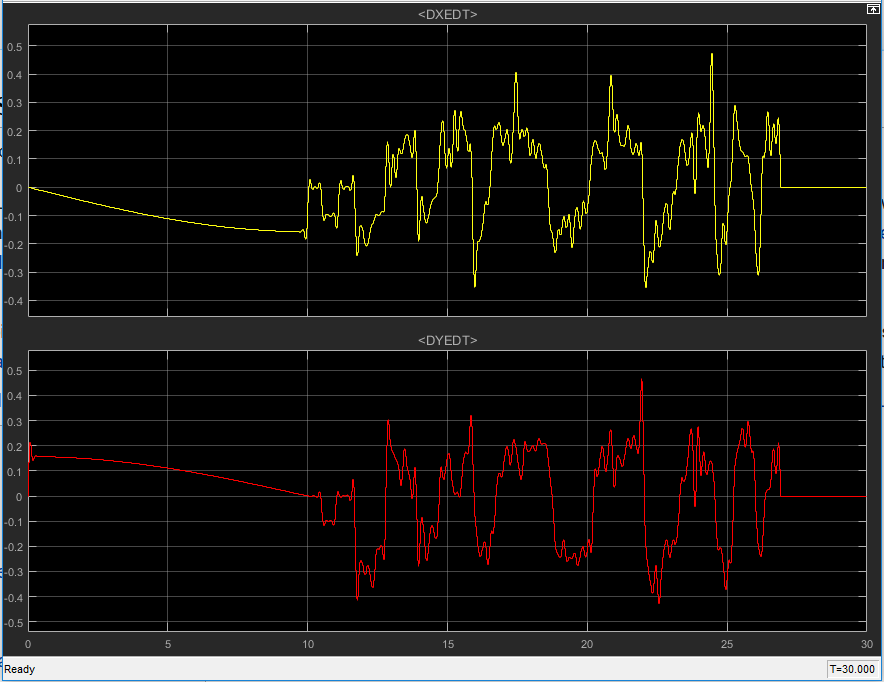

And here's what the signals for {$X_E, Y_E, \theta_1, \theta_2$} look like:

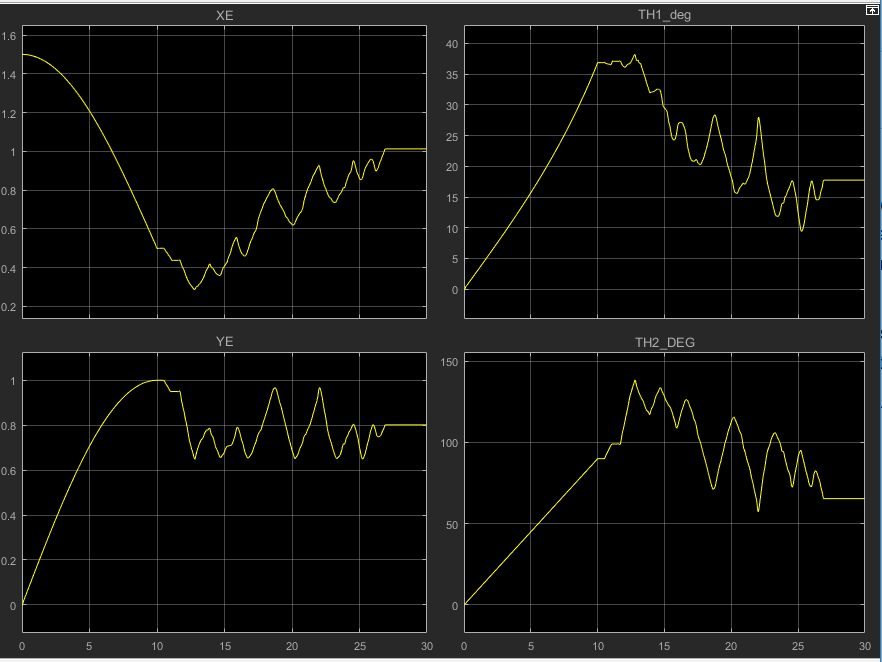

So ? - So when you plot $X_E$ with $Y_E$ you get this:

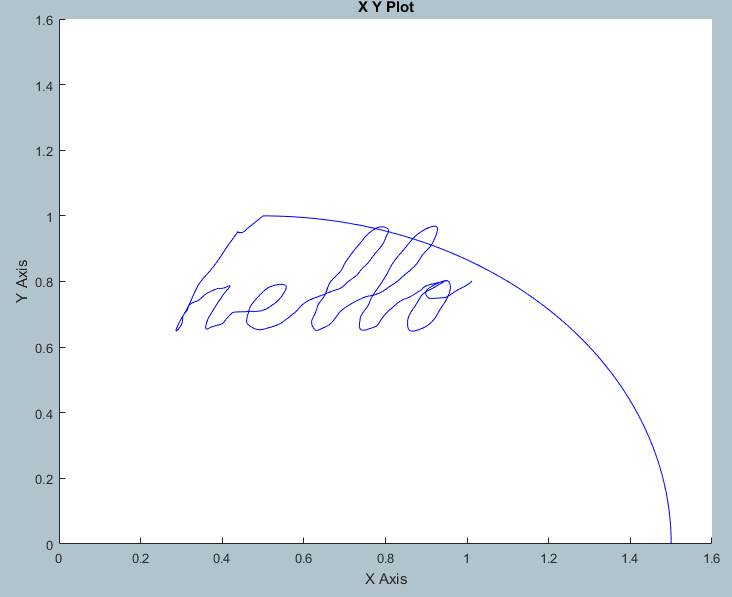

## View the kinematics:

In the same Simulink model mentioned above, I have a Simscape model that will allow you to see an animation of the 2 link manipulator - so check that out: